# Project 1

## 4e) Confirming Equilibrium at T = M

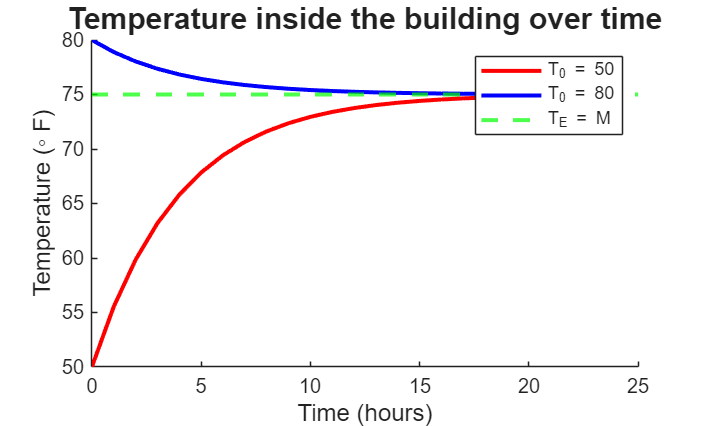

% Set variables
M_0 = 75;            % Temp of environment
t = 0:1:24;          % Time
kappa = 0.25; 

% Solution functions with t = 0
T_50 = M_0 + (50-M_0)*exp(kappa*0)*exp(-kappa.*t); % T_0 = 50
T_80 = M_0 + (80-M_0)*exp(kappa*0)*exp(-kappa.*t); % T_0 = 80

% Plot
figure (); 
hold on;             % Multiple plots
plot(t, T_50,'r','LineWidth',2); 
plot(t, T_80,'b','LineWidth',2);
yline(M_0,'g--','LineWidth',2);                     % Equilibrium
hold off;

% Label graph
title('Temperature inside the building over time','FontSize',15);
xlabel('Time (hours)','FontSize',12);
ylabel('Temperature (◦ F)','FontSize',12);
legend('T_0 = 50', 'T_0 = 80','T_E = M');

## 4f) Effect of Kappa on T & dT/dt

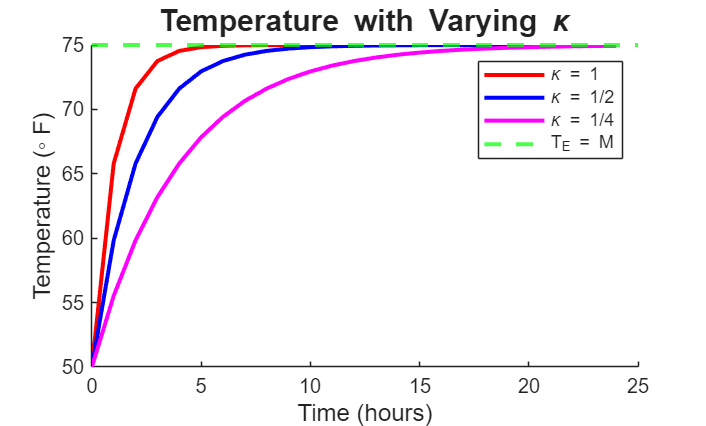

% Solution functions with varrying kappa
T_k1 = M_0 + (50-M_0)*exp(1*0)*exp(-1.*t); % kappa = 1
T_k1_2 = M_0 + (50-M_0)*exp(1/2*0)*exp(-1/2.*t); % kappa = 1/2
T_k1_4 = M_0 + (50-M_0)*exp(1/4*0)*exp(-1/4.*t); % kappa = 1/4

% Plot the solutions with varying kappa
figure ();
hold on;
plot(t, T_k1, 'r', 'LineWidth', 2);
plot(t, T_k1_2, 'b', 'LineWidth', 2);
plot(t, T_k1_4, 'm', 'LineWidth', 2);
yline(M_0,'g--','LineWidth',2);
hold off;

% Label graph
title('Temperature with Varying \kappa','FontSize',15);
xlabel('Time (hours)','FontSize',12);
ylabel('Temperature (◦ F)','FontSize',12);
legend('\kappa = 1', '\kappa = 1/2', '\kappa = 1/4','T_E = M');